# Experiment 10

This Live Script contains the experimental setup described in the section: *"4.3.4.1. Operations planning of integrated T-D systems", *included in the dissertation:

W. González-Vanegas,** "Planning Methodologies for the Operation and Expansion of Distribution Systems Considering the Interactions with the Transmission System"**, Ph.D. dissertation, Dept. of Elect. Electron. and Comp. Eng., National University of Colombia, Manizales, Caldas, 2025.

*Note: MATLAB R2023a is the oldest version where this Live Script was successfully tested. *

## Part I - Create hybrid network

Configure the hybrid case to be analyzed by filling variables `T_case, D_case, bus_T, `and `bus_D,` according to the following table:

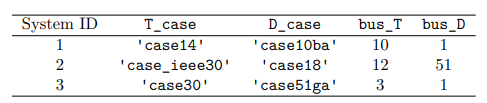

T_case = 'case_ieee30';
D_case = 'case18';
bus_T = 12;
bus_D = 51;

Initialization:

define_constants;    % MATPOWER column indices
rng(10);             % Fix seed for random number generator

Case-specific commands:

mpc_T = loadcase(T_case);
mpc_D = loadcase(D_case);
hybrid_case = [T_case '-' D_case];
id_bus_T = find(mpc_T.bus(:,BUS_I) == bus_T);
id_bus_D = find(mpc_D.bus(:,BUS_I) == bus_D);
order_bus3p = [];
switch hybrid_case    
    case 'case14-case10ba'    % Buses are 10(T) & 1(D)        
        mpc_T.bus(:,BASE_KV) = 138;
        id_branch_bus_D = find(mpc_D.branch(:,F_BUS) == id_bus_D);  % Activate the tap parameter for the first branch(es)
        mpc_D.branch(id_branch_bus_D,TAP) = 1;
    case 'case_ieee30-case18' % Buses are 12(T) & 51(D)
        mpc_D.bus(id_bus_D,BASE_KV) = mpc_T.bus(id_bus_T,BASE_KV);
        mpc_D.bus(id_bus_D-1,BASE_KV) = mpc_T.bus(id_bus_T,BASE_KV);
        mpc_D.bus(:,BS) = 0;
        order_bus3p = [51 50 1 2 9 3 4 5 6 7 8 20 21 22 23 24 25 26];
    case 'case30-case51ga'    % Buses are 3(T) & 1(D)
        id_branch_bus_D = find(mpc_D.branch(:,F_BUS) == id_bus_D);  % Activate the tap parameter for the first branch(es)
        mpc_D.branch(id_branch_bus_D,TAP) = 1;    
end

Plot the single-line diagram of the networks being connected. The nomenclature is as follows:

- Red circles: nodes with demand

- Green circles: nodes with generation

- Brown circles: nodes with generation and demand

- Purple hexagram: buses that are connected to form a T-D Interface

- Blue edges: branchs with transformers

wgv.case_utils.plot_TD_sld(mpc_T,mpc_D,bus_T,bus_D,1)

Look for generator(s) connected to the distribution side of the TD interface and remove them

id_gen_bus_D = find(mpc_D.gen(:,GEN_BUS)==bus_D);
if id_gen_bus_D
    mpc_D.gen(id_gen_bus_D,:) = [];
    mpc_D.bus(id_bus_D,BUS_TYPE) = PQ;
end
mpc_D_aux = mpc_D;

Remove initial demand of bus_T in the transmission network as the distribution network is itself the new demand

mpc_T.bus(bus_T,PD) = 0;
mpc_T.bus(bus_T,QD) = 0;

Run a power flow for the transmission network to get a good starting point, including the equality of voltages at the TD interface

mpc_T = runpf(mpc_T,mpoption('out.all',0,'verbose',0));
mpc_D.bus(id_bus_D,VM) = mpc_T.bus(id_bus_T,VM);
mpc_D.bus(id_bus_D,VA) = mpc_T.bus(id_bus_T,VA);

Ensure equal base voltages at both sides of the TD interface:

mpc_D.bus(id_bus_D,BASE_KV) = mpc_T.bus(id_bus_T,BASE_KV);

Set voltage of reference bus to 1.0 p.u.

id_ref = find(mpc_T.bus(:,2) == REF);
mpc_T.bus(id_ref,VMIN) = 1.0;
mpc_T.bus(id_ref,VMAX) = 1.0;

Connect cases to create a hybrid network with single-phase tranmission and three-phase distribution descriptions

[mpc_hybrid,conn_hybrid_info] = wgv.case_utils.connect_cases(mpc_T,mpc_D,bus_T,bus_D,1);

Unbalance the disribution network changing the load and line parameters:

params = struct('max_ldpf', 1, ...
                'min_ldpf', 0.85, ...
                'max_kW',   1.25, ...
                'min_kW',   0.75, ...
                'rnd_ldpf', 0);
mpc_hybrid = wgv.case_utils.unbalance_case(mpc_hybrid,{'line_params','load'},params);

Run a power flow to get the base case results:

res_ac_hybrid = run_opf(mpc_hybrid,mpoption('out.gen',1),'mpx',mp.xt_3p);

Finally, make some plots with the base case information

if ~isempty(order_bus3p)
    [~,id_perm_bus3p] = ismember(order_bus3p,mpc_hybrid.bus3p(:,1));    
else
    id_perm_bus3p = (1:res_ac_hybrid.dm.elements.bus3p.n);
end

% Per-phase voltage profiles
nb3p = res_ac_hybrid.dm.elements.bus3p.n;
vm3p = table2array(res_ac_hybrid.dm.elements.bus3p.tab(id_perm_bus3p,["vm1","vm2","vm3"]));
figure;
tiledlayout(2,1)
nexttile;
plot(vm3p)
grid on
title('Distribution network - base case');
ylabel('Voltage magnitude (p.u.)')
xlabel('Bus index')
xticks(1:nb3p)
xticklabels(wgv.case_utils.vec2char(mpc_hybrid.bus3p(id_perm_bus3p,1)))
legend({'Phase a', 'Phase b', 'Phase c'})

% Per-phase power factor for power exhange at the TD Interface
Pinter = table2array(res_ac_hybrid.dm.elements.buslink.tab(:,["pg1_start","pg2_start","pg3_start"]));
Qinter = table2array(res_ac_hybrid.dm.elements.buslink.tab(:,["qg1_start","qg2_start","qg3_start"]));
epf = sign(Qinter) .* Pinter./sqrt(Pinter.^2 + Qinter.^2);
nexttile;
bar(epf);
title(sprintf('TD Interface: %d (T)-(D) %d',bus_T,bus_D))
if min(epf) > 0
    ylim([round(min(epf),1)*0.9 round(max(epf),1)*1.1])
else
    ylim([round(min(epf),1)*1.1 round(max(epf),1)*0.9])
end

ylabel('Power factor');
xlabel('Phase')
xticklabels({'a','b','c'})

## Part II - Run ORPD for the distibution network

mpc_hybrid_orpd = mpc_hybrid;
mpc_hybrid_orpd.bus3p(:,[7 8 9]) = 0;
switch hybrid_case    
    case 'case14-case10ba'
        % Set three-phase bus limits        
        mpc_hybrid_orpd.bus3p(:,[10 11]) = repmat([0.95 1.05],nb3p,1);

        % Add a generator at bus 6 of the distribution system
                             %% genid   gbus    status  Vg1 Vg2 Vg3 Pg1 Pg2 Pg3 Qg1 Qg2 Qg3 Pmin Pmax Qmin Qmax 
        mpc_hybrid_orpd.gen3p = [ 1        6        1     1   1   1   0   0   0   0   0   0  2400 2400 -1000 1000];  %% PV

        % Change transformer tap at the substation
        mpc_hybrid_orpd.xfmr3p(end) = 0.98; 
    case 'case_ieee30-case18'
        % Set three-phase bus limits        
        mpc_hybrid_orpd.bus3p(:,[end+1 end+2]) = repmat([0.95 1.05],nb3p,1);        
        
        % Add generators at bus 3 and 21 of the distribution system
                             %% genid   gbus    status  Vg1 Vg2 Vg3 Pg1 Pg2 Pg3 Qg1 Qg2 Qg3 Pmin  Pmax  Qmin Qmax 
        mpc_hybrid_orpd.gen3p = [ 1      21        1     1   1   1   0   0   0   0   0   0  750   2000  -600  600     %% Small hydro
                                  2       3        1     1   1   1   0   0   0   0   0   0  800    800  -200  200];   %% PV     

        % Add capacitor banks at the farthest buses from the substation       
                               %% shuntid  shbus   status  gs1     gs2     gs3     bs1     bs2     bs3
        mpc_hybrid_orpd.shunt3p = [  1      8       1     0       0       0       800     800     800
                                     2     26       1     0       0       0       500     500     500];
        
        % Change transformer tap at the substation
        mpc_hybrid_orpd.xfmr3p(end) = 1.03;
    case 'case30-case51ga'
        % Set three-phase bus limits        
        mpc_hybrid_orpd.bus3p(:,[end+1 end+2]) = repmat([0.9 1.05],nb3p,1);
        
        % Add a generators at buses 9, 31, and 41 of the distribution system
                             %% genid   gbus    status  Vg1 Vg2 Vg3 Pg1 Pg2 Pg3 Qg1 Qg2 Qg3  Pmin  Pmax  Qmin  Qmax 
        mpc_hybrid_orpd.gen3p = [ 1       9        1     1   1   1   0   0   0   0   0   0   45    300  -100  100    %% Small hydro
                                  2      31        1     1   1   1   0   0   0   0   0   0   40    40    -10   10    %% PV
                                  3      41        1     1   1   1   0   0   0   0   0   0   20    80    -35   35];  %% Small hydro

        % Change transformer tap at the substation
        mpc_hybrid_orpd.xfmr3p(end) = 0.965;
end

% Set power factor bounds at the TD Interface
target_epf_lead = 0.9;
target_epf_lagg = 0.95;
mpc_hybrid_orpd.buslink([5 6]) = [target_epf_lead target_epf_lagg];

Set up options for running an ORPD

mpopt_qtpc = mpoption('model','TPC','out.all',0,'verbose',2);
mpopt_qtpc.orpd.tpc.form = 'QUAD';
mpopt_qtpc.orpd.tpc.solver = 'KNITRO'; % Use 'KNITRO', if available
mpopt_qtpc.orpd.tpc.Vref = 'DEFAULT';
mpopt_qtpc.orpd.tpc.buses_T_Vref = [bus_T; wgv.case_utils.find_neighbors(mpc_T,bus_T)];
mpopt_qtpc.orpd.tpc.cost_dev_Vref = 10;
mpopt_qtpc.orpd.tpc.gen3p_const = struct('va',0,'vm',0,'pg',1,'qg',0);   %% If true, fixes balanced operation on the target variable

res_orpd = run_orpd(mpc_hybrid_orpd,mpopt_qtpc,'mpx',wgv.xt_tpc_3p_orpd);

%% Make some plots to compare the optimal solution with the base case

% Voltage magnitudes
figure;
vm_orpd = table2array(res_orpd.dm.elements.bus3p.tab(id_perm_bus3p,["vm1","vm2","vm3"]));
defaultColorsRGB = get(gca, 'ColorOrder');
plot(vm3p)
hold on
for p = 1:3
    plot(vm_orpd(:,p),'color',defaultColorsRGB(p,:),'LineStyle','--','Marker','*')
end
xticks(1:nb3p);
xticklabels(wgv.case_utils.vec2char(mpc_hybrid_orpd.bus3p(id_perm_bus3p,1)));

Id_bus_D = find(id_perm_bus3p == id_bus_D);
plot(Id_bus_D,vm_orpd(Id_bus_D,1),'Marker','hexagram','MarkerSize',8,'MarkerFaceColor',[0.54 0 0.54])
offset = 0.1*(max(vm3p(:))-min(vm3p(:))); 
text(Id_bus_D-0.5, vm_orpd(Id_bus_D,1)-offset, sprintf('%.3f p.u.', vm_orpd(Id_bus_D,1)), ...
     'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom', 'Color', [0.54 0 0.54], 'FontSize', 8);
xlim([0 res_orpd.dm.elements.bus3p.n])
grid on
ylabel('Voltage magnitude (p.u.)')
xlabel('Bus index')
title('Distribution network - ORPD')
lgd = legend({'Phase a - base', 'Phase b - base', 'Phase c - base','Phase a - orpd', 'Phase b - orpd', 'Phase c - orpd'});
lgd.Location = "northoutside";

% Per-phase power factor for power exhange at the TD Interface
Pinter = table2array(res_orpd.dm.elements.buslink.tab(:,["pg1_start","pg2_start","pg3_start"]));
Qinter = table2array(res_orpd.dm.elements.buslink.tab(:,["qg1_start","qg2_start","qg3_start"]));
epf_orpd = sign(Qinter) .* Pinter./sqrt(Pinter.^2 + Qinter.^2);
figure;
tiledlayout(3,1);
nexttile;
bar([epf; epf_orpd]');
hold on;
if any(epf_orpd < 0)
    ylim([-1 0.9*min(epf)])
    yline(-target_epf_lagg,'k--')
else
    ylim([0.9*min(epf) 1])
    yline(target_epf_lead,'k--')
end
title('Power factor at the TD Interface');
xlabel('Phase')
xticklabels({'a','b','c'})
lgn = legend({'base','orpd','Min. PF'});
lgn.Location = "eastoutside";

% Installed three-phase generation
if res_orpd.nm.elements.has_name('gen3p')
    nexttile;
    pg3p_orpd = table2array(res_orpd.dm.elements.gen3p.tab(:,["pg1","pg2","pg3"]));
    qg3p_orpd = table2array(res_orpd.dm.elements.gen3p.tab(:,["qg1","qg2","qg3"]));
    bp = bar(pg3p_orpd','stacked');
    ng3p = size(pg3p_orpd,1);
    for i=1:ng3p
        bp(i).FaceColor = defaultColorsRGB(i+2,:);
    end
    ylabel('Pg (kW)')
    xlabel('Phase')
    xticklabels({'a','b','c'})
    lgn = legend(cellfun(@(x)(['gen ' x]),wgv.case_utils.vec2char((1:ng3p)'),'UniformOutput',false));
    lgn.Location = "eastoutside";
    nexttile
    bp = bar(qg3p_orpd','stacked');
    for i=1:ng3p
        bp(i).FaceColor = defaultColorsRGB(i+2,:);
    end
    ylabel('Qg (kVAr)')
    xlabel('Phase')
    xticklabels({'a','b','c'})    
end

Finally, we compare some results obtained for the tranmission network between the base case and the ORPD results

% Voltage magnitude
vm1p = res_ac_hybrid.dm.elements.bus.tab.vm;
vm1p_orpd = res_orpd.dm.elements.bus.tab.vm;
figure;
tl = tiledlayout(2,1);
nexttile
plot(vm1p,'Color',defaultColorsRGB(3,:));
hold on;
plot(vm1p_orpd,'Color',defaultColorsRGB(4,:));
plot(id_bus_T, vm1p_orpd(id_bus_T,1),'hexagram','MarkerSize',8,'MarkerFaceColor',[0.54 0 0.54], 'MarkerEdgeColor',[0.54 0 0.54])
offset = 0.5*(max(vm1p_orpd(:))-min(vm1p_orpd(:))); 
text(id_bus_T-0.5, vm1p_orpd(id_bus_T,1)-offset, sprintf('%.3f p.u.', vm1p_orpd(id_bus_T,1)), ...
     'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom', 'Color', [0.54 0 0.54], 'FontSize', 8);
grid on
ylabel('|v| (p.u.)')
xlabel('Bus index')
lgn = legend({'base','orpd'});
lgn.Location = "eastoutside";

% Branch flows
pbr_from = res_ac_hybrid.dm.elements.branch.tab.pl_to;
pbr_from_orpd = res_orpd.dm.elements.branch.tab.pl_to;
nexttile
plot(pbr_from,'Color',defaultColorsRGB(3,:));
hold on;
plot(pbr_from_orpd,'Color',defaultColorsRGB(4,:));
grid on
ylabel('Pbr (kW)')
xlabel('Branch index')
title(tl,'Tranmission network')

% Generation
pg = res_ac_hybrid.dm.elements.gen.tab.pg;
qg = res_ac_hybrid.dm.elements.gen.tab.qg;
pg_orpd = res_orpd.dm.elements.gen.tab.pg;
qg_orpd = res_orpd.dm.elements.gen.tab.qg;
figure;
tl = tiledlayout(2,1);
nexttile
bar([pg pg_orpd])
ylabel('Pg (kW)')
xlabel('Generator index')
lgn = legend({'base','orpd'});
lgn.Location = "eastoutside";
nexttile
bar([qg qg_orpd])
ylabel('Qg (kW)')
xlabel('Generator index')
title(tl,'Transmission network')